# **Week2 - Optical Channel with BPSK**

The code below implements a preliminary model of an optical channel without DSPs and aims to investigate the feasibility of the model and the variation of the bit error rate (BER) with the signal-to-noise ratio (SNR)

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Modulation

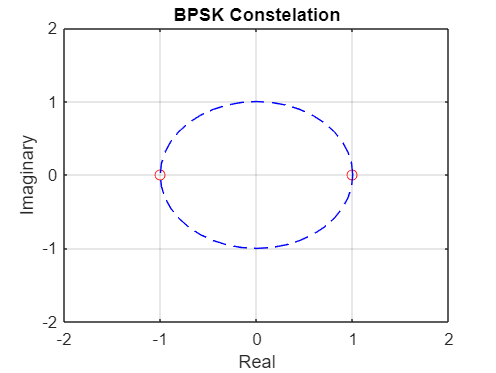

clear all; clearvars;

% Modulation parameters
M = 2; % Modulation order
k = log2(M); % Bits per symbol

% Visualising constellation
alphabet = 0:M-1;
symbols = pskmod(alphabet, M);
plot(real(symbols), imag(symbols), "ro");
title("BPSK Constelation");
xlabel("Real");
ylabel("Imaginary");
grid on;
hold on;
phase = [0:pi/20:2*pi];
circleX = cos(phase); circleY = sin(phase);
plot(circleX, circleY, "b--");
xlim([-2,2]); ylim([-2,2])
hold off

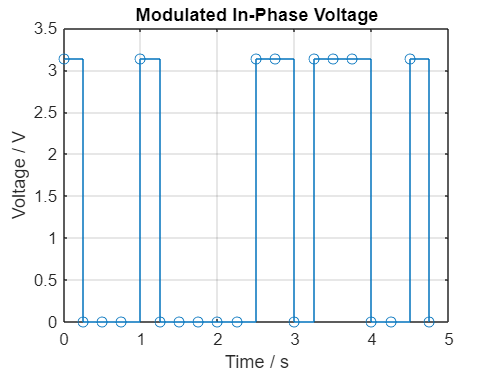


% Generating random bit sequence(s)
NSymb = 500000; % No. of symbols
SpS = 1; % Samples per symbol
Rs = 4; % Symbol rate in s
NSequences = 12; % No. of bit sequences

sourceBits = randi([0 1], NSymb*SpS*k, NSequences); % Vector of source bits
sourceSymbols = pskmod(sourceBits, M); % Maps integer vector to symbol vector

T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% Modulating current with generated symbols
DCOffset = 0; % DC offset of modulated current in V
Vmax = 1; % Sets the maximum value of the voltage
voltageLevels = [0, pi]';
realVals = [1 -1]'; % Storing the unique real values in the symbol constellation
imagVals = [0, 0]'; % Storing the unique imaginary values in the symbol constellation

vI = ones(size(sourceSymbols));
vQ = ones(size(sourceSymbols));

% Mapping the distinct real & imaginary values to their respective voltage levels
for i=1:M
    vI(abs(real(sourceSymbols) - realVals(i)) < 1e-14) = voltageLevels(i);
    vQ(abs(imag(sourceSymbols) - imagVals(i)) < 1e-14) = voltageLevels(i);
end

% testVI = zeros(NSymb*SpS, 1); testVQ = testVI; % Test voltages which do not modulate the amplitude

% Visualising in-phase and quadrature currents
stairs(t(1:20), vI(1:20,1), "o-");
title("Modulated In-Phase Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
grid on

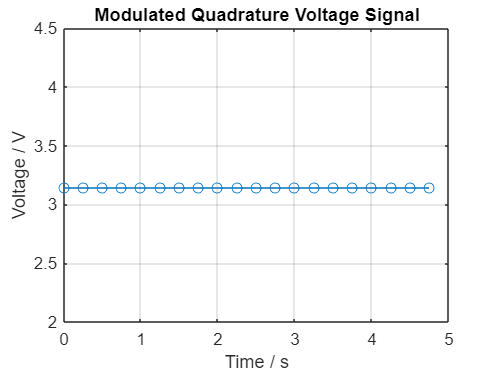


stairs(t(1:20), vQ(1:20,1), "o-");
title("Modulated Quadrature Voltage Signal")
xlabel("Time / s")
ylabel("Voltage / V")
grid on

### Pulse Shaping

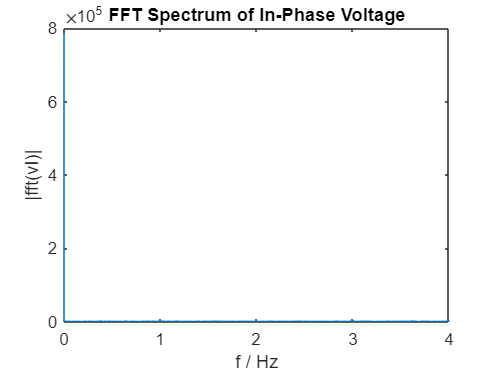

% Frequency spectrum of voltage waveform before filtering
fft_vI = fft(vI(:,1));
freqArr = [0:NSymb*SpS - 1]/(T*NSymb*SpS);
plot(freqArr, abs(fft_vI));
title("FFT Spectrum of In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(vI)|");

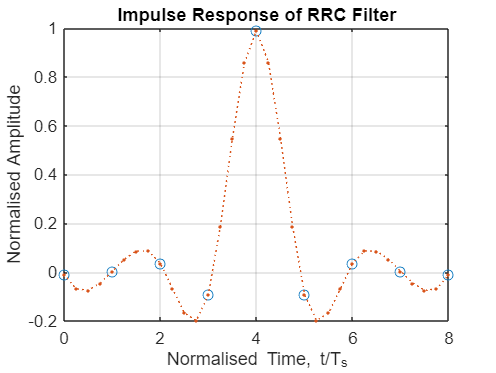


% Visualisation of RRC filter
filterSpan = 8;
filterResponse = rcosdesign(0.5, filterSpan, SpS);
samples = 0:size(filterResponse,2)-1; samples_interp = 0:0.25:size(filterResponse,2)-1;
filterResponse_interp = interp1(samples, filterResponse, samples_interp, "spline");
plot(samples, filterResponse, "o", samples_interp, filterResponse_interp, ":.");
title('Impulse Response of RRC Filter');
xlabel('Normalised Time, t/T_s');
ylabel('Normalised Amplitude');
grid on

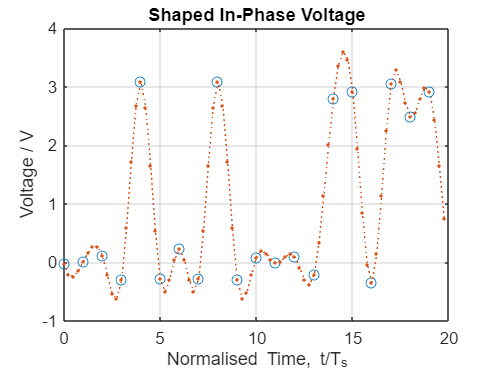


% Using RC filter to shape vI and vQ
shapedVI = upfirdn(vI, filterResponse, SpS, 1);
shapedVQ = upfirdn(vQ, filterResponse, SpS, 1);

% Visualising pulse-shaped voltages
shapedVI_t = 0:size(shapedVI,1)-1; shapedVI_t_interp = 0:0.25:size(shapedVI,1)-1;
shapedVI_interp = interp1(shapedVI_t, shapedVI, shapedVI_t_interp, "spline");
plot(shapedVI_t(1:20), shapedVI(1:20,1), "o", shapedVI_t_interp(1:80), shapedVI_interp(1:80), ":.");
title("Shaped In-Phase Voltage")
ylabel("Voltage / V")
xlabel('Normalised Time, t/T_s');
grid on

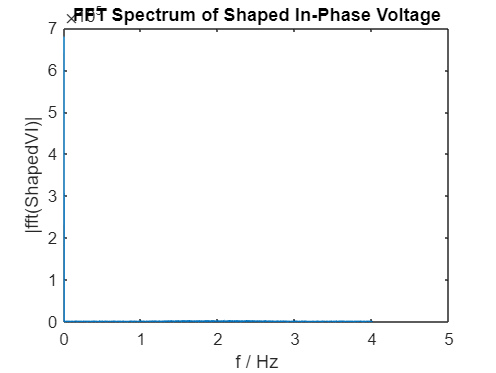


% Frequency spectrum of voltage waveform after filtering
fft_shapedVI = fft(shapedVI(:,1));
freqArr = [0:NSymb*SpS - 1 + filterSpan]/(T*NSymb*SpS);
plot(freqArr, abs(fft_shapedVI));
title("FFT Spectrum of Shaped In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(ShapedVI)|");
hold off

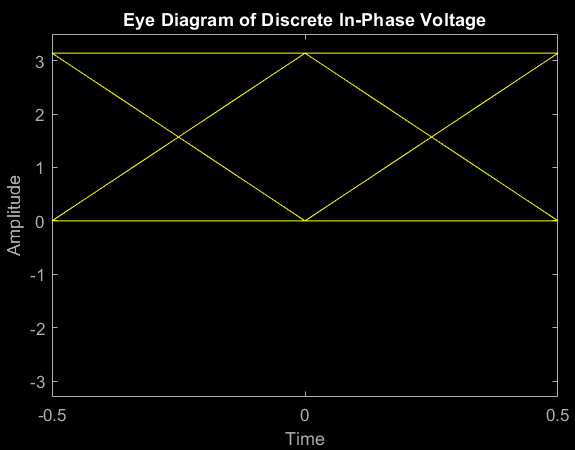


% Eye diagram of voltage waveform before filtering
eyediagram(vI(1:1000,1), SpS*2);
title("Eye Diagram of Discrete In-Phase Voltage")

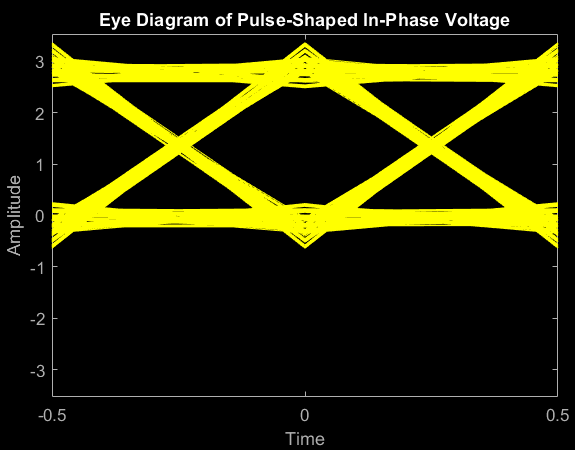

eyediagram(shapedVI(1:1000,1), SpS*2);
title("Eye Diagram of Pulse-Shaped In-Phase Voltage")

### IQ Modulation

% Initialising laser parameters
centreLambda = 299792458*2.5;
lineWidth = 0;
laserPw_dBm = 0;

% Generating output from laser
laserE = LaserModified(laserPw_dBm, centreLambda, lineWidth, SpS, Rs, NSymb, 1);

% Visualising output from laser
t_interp = [0:0.25:NSymb*SpS - 1]*T;
E_interp = interp1(t, real(laserE), t_interp, "spline")';
plot(t(1,1:20), real(laserE(1:20,1)), "o", t_interp(1,1:80), E_interp(1:80,1),":.");
title("Laser Output")
xlabel("Time/s")
ylabel("Electric Field / Vm^{-1}")
grid on

% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi
modOpticSig = IQModulatorModified(vI, vQ, laserE, Vpi);

% Visualising modulated optic signal
modOpticSig_interp = interp1(t, real(modOpticSig), t_interp, "spline");
plot(t(1:20), real(modOpticSig(1:20,1)), "o", t_interp(1:80), modOpticSig_interp(1:80,1),":.");
title("Modulated Optical Signal")
xlabel("Time/s")
ylabel("Electric Field / Vm^{-1}")
grid on

## Optical Channel

### Adding AWGN

% Adding AWGN to laser output
SNRb_dB = [0:NSequences-1]'; % SNR per symbol in dB
SNRb_Lin = zeros(size(SNRb_dB));  
AWGN_StdDev = zeros(size(SNRb_dB));
powerPerSymb = mean(real(modOpticSig).^2,"all");

for i=1:NSequences
    SNRb_Lin(i,1) = 10^(SNRb_dB(i,1)/10); % linear SNR per symbol
    AWGN_StdDev(i,1) = sqrt(powerPerSymb/SNRb_Lin(i,1)); % AWGN Standard deviation
    modOpticSig_AWGN(:,i) = modOpticSig(:,i) + AWGN_StdDev(i,1)*randn(size(modOpticSig, 1),1); % Noisy laser output
end

% channelOut = modOpticSig; % Channel output without AWGN
channelOut = modOpticSig_AWGN; % Channel output with AWGN

### Adding CD

## Receiver

### Optical Front-End

% Generating Local optical signal for coherent detection
Elo = LaserModified(0, centreLambda, 0, SpS, Rs, NSymb, 1); 

% Visualising locally generated optical signal
Elo_interp = interp1(t, real(Elo), t_interp, "spline")';
plot(t(1:20), real(Elo(1:20,1)), "o", t_interp(1:80), Elo_interp(1:80,1),":.");
title("Locally Generated Optical Signal")
xlabel("Time/s")
ylabel("Electric Field / Vm^{-1}")
grid on

% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

count = 1;

for i=1:size(channelOut,2)
    OpticFEOut(:,count:count+1) = OpticalFrontEnd(channelOut(:,i), Elo, eta_ph, 1); % Output from optical front-end
    count = count+2;
end

% Visualising output from optical front-end
currI_interp = interp1(t, OpticFEOut(:,1), t_interp, "spline")';
currQ_interp = interp1(t, OpticFEOut(:,2), t_interp, "spline")';

plot(t(1:20), OpticFEOut(1:20,1), "o", t_interp(1:80), currI_interp(1:80,1) ,":."); % In-phase current
title("In-Phase Current")
xlabel("Time / s")
ylabel("Current / A")
grid on

plot(t(1:20), OpticFEOut(1:20,2), "o", t_interp(1:80), currQ_interp(1:80,1) ,":."); % In-phase current
title("Quadrature Current")
xlabel("Time / s")
ylabel("Current / A")
grid on

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

sampledFEOut_I = TIA_Gain*OpticFEOut(1:SpS:end, 1:2:end);
sampledFEOut_Q = TIA_Gain*OpticFEOut(1:SpS:end, 2:2:end);

### Decision

% Scaling factor between output of IQM and output of optical front-end
scaleFactor = TIA_Gain*eta_ph*(1e-3*10^(laserPw_dBm/10))/2;

% Cancelling the scaling factor
scaledVoltageI = sampledFEOut_I/scaleFactor;
scaledVoltageQ = sampledFEOut_Q/scaleFactor;

% Visualising distribution of voltages using a histogram
histogram(scaledVoltageI,200)
title("Histogram of Voltages")
ylabel("Samples")
xlabel("Voltage / V")
xlim([-3 3])

decodedSymbolsI = ones(size(scaledVoltageI));

% Mapping scaled voltages to inital in-phase component of the symbol
% constellation.
% Quadrature component is ignored as it is the same value for all symbols.
% Maximum likelihood estimation, based on the Euclidian distance between the recieved voltage points
% and those corresponding to the symbols, is used.

decodedSymbolsI(scaledVoltageI < 0) = -1;
decodedSymbolsI(scaledVoltageI >= 0) = 1;

decodedSymbols = decodedSymbolsI; % Quadrature component is ignored
decodedInts = pskdemod(decodedSymbolsI, M);
decodedBits = int2bit(decodedInts, k);

BER = zeros(NSequences,1);
numErrors = zeros(NSequences,1);

for i=1:NSequences
    [numErrors(i,1), BER(i,1)] = biterr(sourceBits(:,i), decodedBits(:,i));
end

semilogy(SNRb_dB, BER, 'o-')
title("BER vs. SNR")
ylabel("BER")
xlabel("SNR per symbol / dB")
grid on

